# Laboratório de Controle - Aula 1 - 2022-1

## Nome: 

## Introdução à disciplina e recursos utilizados

Definição de seus parâmetros.

datetime('now')
pwd
turma=0;
I=0;
[k,m]=init(turma,I)

**Atividade 1: Seja o sistema massa-mola-amortecedor mostrado na figura 1, a equação diferencial que gere seu comportamento e a função de transferência que relaciona a força aplicada F e o deslocamento X**


$$m\ddot{x}+b\dot{x}+kx=f(t)$$



$$\frac{X(s)}{F(s)}=G(s)=\frac{1}{ms^2+bs+k}$$


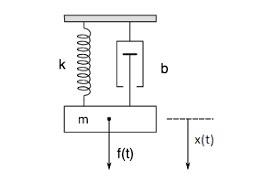Figura 1.

**Execute a seção de código a seguir, e responda as perguntas.**


b=1.41*sqrt(k*m);
g=tf(1,[m b k]);
step(g);title('Figura 2: resposta ao degrau');


1.1 Qual foi a força aplicada (N)? 

Resposta: 

1.2 Qual foi o deslocamento da massa (m)?

Resposta:

**Atividade 2. Execute o app aula1.app para responder as perguntas que seguem.**

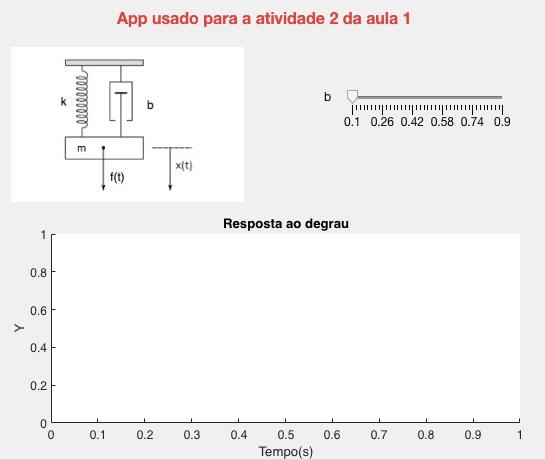Figura 3

2.1 Qual o efeito do parâmetro b do amortecedor no valor de regime?

Resposta:

2.2 Qual o efeito do parâmetro b do amortecedor na sobreelevação?

Resposta:

**Atividade 3. Execute os comandos do script abaixo e faça a simulação no simulink**

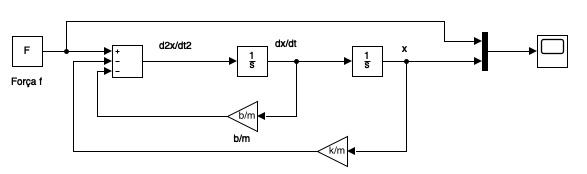

Figura 4

Atividade 3.1 Ajuste o valor da força F aplicada de modo que a massa se desloque 1m, mostrada na simulação da figura 5.

F=1; % Ajustar
out=sim('aula1_mma_2018',20); 
y=out.X(:,[ 2 3]);
t=out.X(:,1);
plot(t,y(:,[2,1]));
grid;title('Fig5. - Simulação do sistema mma no simulink');
xlabel('Tempo(s');ylabel('Deslocamento(m)');



**Atividade 4. Assistam o video abaixo e respondam as perguntas que seguem. O trecho do livro pode ser usado para complementar o video**

Video: [Sistemas de controle](https://youtu.be/bWSkzcdooC4)

Livro: [Ogata](https://drive.google.com/file/d/1SgVr6PlMiKs3IRNhhIN1-cDBJWfP1bZ1/view?usp=sharing)

4.1 Em que situações não é necessário um sistema de controle em malha fechada?

Resposta:

4.2 Qual a definição de erro em um sistema de controle?

Resposta:

4.3 Seja o sistema de controle de velocidade mostrado na figura 1.1 de [Ogata](https://drive.google.com/file/d/1SgVr6PlMiKs3IRNhhIN1-cDBJWfP1bZ1/view?usp=sharing). Que tipo de distúrbio pode ocorrer nesta sistema e que efeito ele tem sobre o sinal de controle?

Resposta: